## 초기화

clc;
clear variables; 
clear all;

mode = 1; % 0: simulation mode / 1: real mode

## 텔로 이륙하기

if (mode > 0)
    my_tello = ryze();
    takeoff(my_tello);
    pause(3); % wait for stability, 안정화 후 사진 촬영을 위함
else
    my_tello = 0;
end

## 영상 가져오기

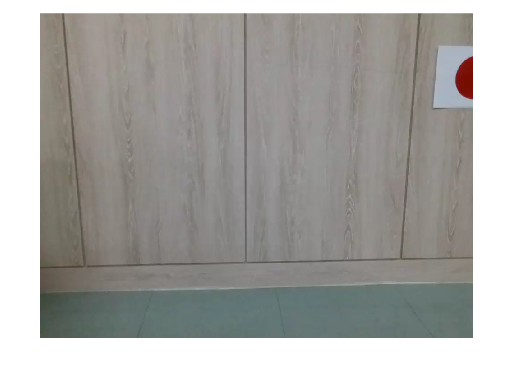

if(mode > 0)
    global my_camera;
    my_camera = camera(my_tello); % 카메라 불러옴
    img = snapshot(my_camera); % 이미지 받음
    
    % imwrite(img, 'snapshot.png');
    % 시뮬레이션을 돌릴 때 사용할 사진 촬영 코드
else
    img = imread('snapshot.png');
end
imshow(img)

## 붉은색 공 추적하기 - 공이 화면 중앙에 오도록 제어하기

img = 720×960×3 uint8 배열
img(:,:,1) =

   151   151   150   150   148   148   148   148   150   150   150   150   148   148   146   146   145   144   145   145   146   146   146   146   145   144   146   148   150   151   144   140   142   143   144   147   148   147   146   146   146   146   148   149   149   149   148   148   150   148   148   148   148   148   148   148   148   148   148   148   150   148   148   148   151   151   150   150   150   150   148   150   150   150   152   152   152   152   150   150   146   144   146   148   148   148   148   148   148   149   150   154   153   150   150   150   151   151   151   151   151   150   150   150   151   151   151   151   152   152   152   152   151   151   151   152   152   152   152   153   153   153   153   154   154   154   154   154   153   151   151   151   151   151   153   154   154   154   154   153   153   153   150   150   150   149   149   149   148   147   148   148   149   149   150   151   153   151   149   149 

flag = logical
   1


img = 720×960×3 uint8 배열
img(:,:,1) =

    57    57    57    57    57    56    56    56    57    57    57    57    57    57    56    56    55    55    54    55    55    56    58    59    58    56    53    53    53    54    55    55    56    55    55    55    53    53    53    54    56    58    58    58    58    56    56    56    56    56    56    56    56    56    55    55    55    54    53    53    52    52    52    54    55    56    58    58    58    56    58    59    60    59    56    55    55    54    56    57    55    55    56    58    58    58    58    58    58    56    56    56    58    56    56    56    56    56    55    54    52    52    53    53    54    54    54    55    55    54    57    58    56    58    59    59    59    59    58    58    56    56    55    55    55    55    54    54    53    51    51    53    53    53    54    55    55    55    54    53    53    53    53    53    53    53    53    53    53    53    53    53    53    53    53    53    53    53    53    53 

flag = logical
   1


img = 720×960×3 uint8 배열
img(:,:,1) =

   120   118   119   118   115   113   112   111   111   114   118   121   122   125   125   126   122   118   122   118   112   113   116   118   118   119   120   119   117   118   116   116   114   114   115   115   115   115   117   118   117   117   115   112   111   114   117   118   115   110   112   111   112   112   112   115   111   106   105   104   105   108   112   112   111   108   107   106   106   108   112   111   111   113   113   114   113   113   114   115   117   118   119   117   110    83    69    72    73    73    73    87   104   108   111   113   104   109   111   109   104   100    97    93   101   102   100   101   100    98    96    98   102   104   105   104   104   102    98    99    99   101   104   105   106   107   108   104   100   103    99   101    96    92    94    98    98    98    98    99    99    98    96    96    93    92    91    91    90    90    90    90    89    87    86    86    86    87    89    89 

flag = logical
   1


img = 720×960×3 uint8 배열
img(:,:,1) =

   119   118   114   114   115   115   117   118   119   119   120   120   121   121   117   118   116   117   117   117   116   116   117   118   120   121   120   120   122   125   129   127   125   124   122   122   122   122   122   122   122   121   122   124   125   126   126   126   125   124   124   122   124   124   124   124   122   122   122   122   121   121   121   121   122   122   122   122   120   120   119   118   117   117   117   117   118   117   115   117   117   118   120   121   122   122   122   124   124   122   121   121   120   118   114   115   117   117   118   119   119   121   121   121   121   120   120   121   120   120   120   121   121   121   120   119   118   117   117   117   117   117   118   118   118   118   117   115   116   115   121   124   120   124   125   128   128   128   129   129   129   125   123   122   122   122   127   129   131   131   131   130   128   127   124   123   122   122   121   122 

flag = logical
   1


img = 720×960×3 uint8 배열
img(:,:,1) =

    55    51    50    50    50    51    54    55    55    55    56    56    55    55    55    54    52    52    53    53    51    49    48    49    56    53    53    57    54    53    53    54    52    52    53    53    56    57    58    55    55    55    56    57    57    56    55    55    53    53    53    54    54    54    54    54    53    52    52    52    55    55    56    56    55    55    54    54    53    54    55    57    57    57    57    57    56    54    53    53    53    53    53    53    53    51    51    51    53    54    55    55    56    56    56    57    54    54    56    58    58    58    60    60    57    57    57    57    58    60    60    61    59    59    61    62    60    60    59    59    58    59    58    58    57    56    56    56    58    58    59    60    60    60    60    56    64    65    65    65    63    63    64    65    65    64    61    62    62    63    64    65    68    68    68    68    66    66    70    70 

flag = logical
   1


done


img = 720×960×3 uint8 배열
img(:,:,1) =

    55    51    50    50    50    51    54    55    55    55    56    56    55    55    55    54    52    52    53    53    51    49    48    49    56    53    53    57    54    53    53    54    52    52    53    53    56    57    58    55    55    55    56    57    57    56    55    55    53    53    53    54    54    54    54    54    53    52    52    52    55    55    56    56    55    55    54    54    53    54    55    57    57    57    57    57    56    54    53    53    53    53    53    53    53    51    51    51    53    54    55    55    56    56    56    57    54    54    56    58    58    58    60    60    57    57    57    57    58    60    60    61    59    59    61    62    60    60    59    59    58    59    58    58    57    56    56    56    58    58    59    60    60    60    60    56    64    65    65    65    63    63    64    65    65    64    61    62    62    63    64    65    68    68    68    68    66    66    70    70 

flag = logical
   0


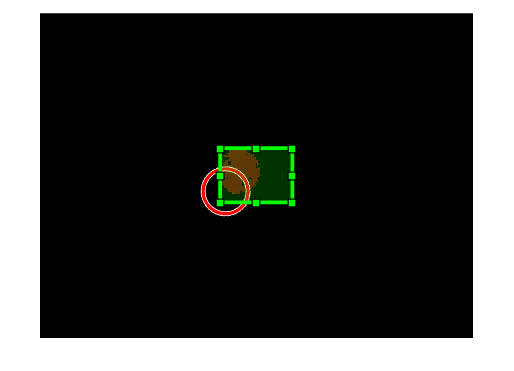

[height, width, channels] = size(img);
center = [width/2, height/2]; % 중앙
offset = [round(width/12), round(height/12)]; % 중앙 언저리

flag = true; % 제어 시작 flag

ball_pos = zeros();
ball_radius = zeros();

while(flag)
    [ball_pos, ball_radius] = FindRedBall(img);
    if ball_radius == 0
        % 옆으로 0.2m
        moveright(my_tello, 'Distance', 0.2, 'WaitUntilDone', false);
        pause(1);
        img = snapshot(my_camera);
    else
        displace = (ball_pos - center);
        [img, flag] = MoveAndSnap(mode, my_tello, img, displace, offset)
        drawrectangle('Position', [center - offset, offset * 2], 'Color', [0 1 0]);
        % a = input('press enter'); %Enter 눌러 드론 이동
    end
end

## 초록색 공 추적하기 - 공이 화면 중앙에 오도록 제어하기

img = 720×960×3 uint8 배열
img(:,:,1) =

   142   142   142   142   143   143   143   143   142   142   142   142   143   143   143   143   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   140   140   140   140   142   142   142   142   140   140   140   140   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   143   143   143   143   143   143   143   143   143   143   143   143   142   142   142   142   143   143   143   143   143   143   143   142   140   139   139   142   142   144   144   145   144   144   142   140   139   140   143   144   143   143   143   143   143   143   143   143   143   143   143   143   144   144   144   144   144   144   144   144   144   144   144   144   143   143   143   143   143   143   143   143   144   144   144   144   144   144   144   144   143   144   145   145   144   143   143   143 

flag = logical
   1


img = 720×960×3 uint8 배열
img(:,:,1) =

   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   134   134   135   138   138   139   139   137   133   134   135   135   135   135   135   135   134   134   134   134   133   133   133   132   133   133   133   133   134   134   134   134   135   135   135   134   132   134   134   134   135   137   137   137   137   137   137   137   135   135   135   135   136   136   136   136   136   136   136   136   135   135   135   135   134   134   134   134   135   135   135   135   135   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   134   134   134   134   135   135   135   135   135   135   135   135   135   135   135   135   134   134   134   134   134   134   134   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   136   136   137   137   136   136   135   135   135 

flag = logical
   1


done


img = 720×960×3 uint8 배열
img(:,:,1) =

   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   134   134   135   138   138   139   139   137   133   134   135   135   135   135   135   135   134   134   134   134   133   133   133   132   133   133   133   133   134   134   134   134   135   135   135   134   132   134   134   134   135   137   137   137   137   137   137   137   135   135   135   135   136   136   136   136   136   136   136   136   135   135   135   135   134   134   134   134   135   135   135   135   135   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   134   134   134   134   135   135   135   135   135   135   135   135   135   135   135   135   134   134   134   134   134   134   134   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   136   136   137   137   136   136   135   135   135 

flag = logical
   0


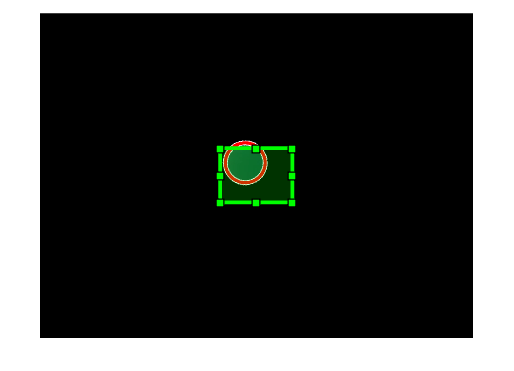

[height, width, channels] = size(img);
center = [width/2, height/2]; % 중앙
offset = [round(width/12), round(height/12)]; % 중앙 언저리

flag = true; % 제어 시작 flag

while(flag)
    [ball_pos, ball_radius] = FindGreenBall(img);
    if ball_radius == 0
        moveup(my_tello, 'Distance', 0.2, 'WaitUntilDone', false);
        pause(0.4);
        img = snapshot(my_camera);
    else
        displace = (ball_pos - center);
        [img, flag] = MoveAndSnap(mode, my_tello, img, displace, offset)
        drawrectangle('Position', [center - offset, offset * 2], 'Color', [0 1 0]);
        % a = input('press enter'); %Enter 눌러 드론 이동
    end
end

## 파란색 공 추적하기 - 공이 화면 중앙에 오도록 제어하기

img = 720×960×3 uint8 배열
img(:,:,1) =

   130   130   130   130   129   129   129   129   128   128   128   128   129   129   130   130   133   133   132   132   133   133   133   133   133   132   130   130   128   128   127   128   130   131   131   132   131   131   131   131   131   130   131   131   131   132   132   132   130   130   128   127   128   129   132   132   132   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   132   132   132   132   132   130   130   130   130   130   130   132   132   132   132   132   132   132   132   132   132   132   132   132   132   132   132   132   132   133   133   133   133   133   133   133   133   132   132   132   132   132   132   132   132   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   132   132   133   133 

flag = logical
   1


img = 720×960×3 uint8 배열
img(:,:,1) =

   133   133   133   134   133   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   133   132   132   130   130   132   132   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   134   134   134   134   134   133   133   133   133   133   133   133   133   133   133   132   132   133   133   134   134   134   134   134   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   133   134   134   135   135   135   135   135   135   135   135   135   135   135   135   137   137   137   137   137   137   137   137   137   137   137   137   137   137   137   137   137   137   137   137   134   134   134   134   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135 

flag = logical
   1


img = 720×960×3 uint8 배열
img(:,:,1) =

   126   127   126   125   125   126   127   129   127   128   128   127   127   127   127   127   130   130   131   132   133   132   130   128   128   128   128   128   130   130   130   130   128   127   126   126   125   126   127   127   128   128   128   129   128   128   128   128   128   128   128   128   129   129   128   128   127   127   127   127   127   128   128   128   129   129   127   127   128   128   128   129   129   129   129   130   129   129   129   129   129   129   129   129   130   130   128   128   130   130   130   128   130   130   131   131   129   129   129   129   130   130   130   130   132   132   132   132   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   132   132   132   132   132   130   130   130   130   130   130   130   130   133   133   133   132   132   131   133   133   133   132   132   133   133   133   133   133 

flag = logical
   1


img = 720×960×3 uint8 배열
img(:,:,1) =

   129   129   131   131   131   130   130   130   130   130   130   130   130   131   133   133   134   133   133   133   132   132   132   132   130   132   134   135   134   134   134   135   137   137   134   134   133   134   133   133   133   132   132   134   132   133   134   134   133   134   134   134   135   135   135   135   134   134   134   134   135   135   135   135   135   135   135   135   135   135   135   135   137   137   135   135   137   138   137   135   135   134   135   137   134   134   134   134   134   133   133   133   134   134   134   134   135   135   134   134   134   134   134   134   134   134   134   134   134   136   136   135   135   135   135   135   135   135   135   133   132   132   132   134   135   135   135   135   136   135   136   136   135   136   136   136   136   136   136   136   136   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   136 

flag = logical
   1


done


img = 720×960×3 uint8 배열
img(:,:,1) =

   129   129   131   131   131   130   130   130   130   130   130   130   130   131   133   133   134   133   133   133   132   132   132   132   130   132   134   135   134   134   134   135   137   137   134   134   133   134   133   133   133   132   132   134   132   133   134   134   133   134   134   134   135   135   135   135   134   134   134   134   135   135   135   135   135   135   135   135   135   135   135   135   137   137   135   135   137   138   137   135   135   134   135   137   134   134   134   134   134   133   133   133   134   134   134   134   135   135   134   134   134   134   134   134   134   134   134   134   134   136   136   135   135   135   135   135   135   135   135   133   132   132   132   134   135   135   135   135   136   135   136   136   135   136   136   136   136   136   136   136   136   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   136 

flag = logical
   0


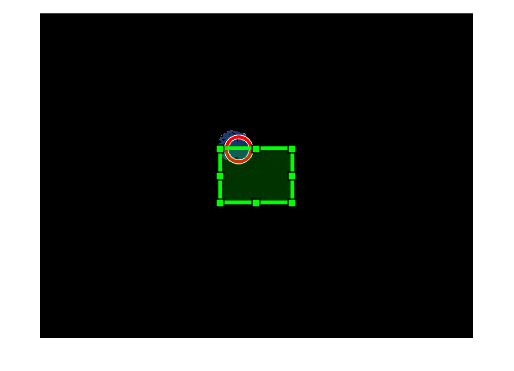

[height, width, channels] = size(img);
center = [width/2, height/2]; % 중앙
offset = [round(width/12), round(height/12)]; % 중앙 언저리

flag = true; % 제어 시작 flag


while(flag)
    [ball_pos, ball_radius] = FindBlueBall(img);
    if ball_radius == 0
        moveright(my_tello, 'Distance', 0.2, 'WaitUntilDone', false);
        pause(1);
        img = snapshot(my_camera);
    else
        displace = (ball_pos - center);
        [img, flag] = MoveAndSnap(mode, my_tello, img, displace, offset)
        drawrectangle('Position', [center - offset, offset * 2], 'Color', [0 1 0]);
        % a = input('press enter'); %Enter 눌러 드론 이동
    end
end

## 텔로 착륙하기

if (mode>0)
    land(my_tello);
end
clear variables;



